# Simulate the process u_t in section 2.4

% Example of Kalman filter
% Simulate N samples of a process to test your code.
y = load("Code\data\tar2.dat"); % Simulated data

N = length(y);

% Define the state space equations.
A = [1.2 0
     0   1];
C = [1 0];
Re = [.004 0 ; 0 0]; % State covariance matrix
Rw = 1.25; % Observation variance

% Set some initial values
Rxt1 = 10 * eye(2); % R{1|0}^{x,x}
het = zeros(1,N); % Estimated prediction error.
xt = zeros(2,N); % Estimated states.
yhat1 = zeros(N + 1,1); % Estimated 1-step prediction.
yhat2 = zeros(N + 2,1); % Estimated 2-step prediction.

% Where should the loop start and stop?
for t = 2 : N

    % Update the predicted state
    xt1 = A * xt(:,t-1); % x{t|t-1}
    Ct = [1 0]; % C{t|t-1}

    % Update the parameter estimates.
    Ry = Ct * Rxt1 * Ct' + Rw; % R{t|t-1}^{y,y}
    Kt = Rxt1 * Ct'/Ry; % Kt
    yhat = Ct * xt1; % yhat{t|t-1}
    het(t) = y(t) - yhat; % Prediction error
    xt(:,t) = xt1 + Kt * het(t); % x{t|t}

    % Update the covariance matrix estimates.
    Rxt =  Rxt1 - Kt * Ry * Kt'; % R^{x,x}_{t|t}
    Rxt1 = A * Rxt * A' + Re; % R^{x,x}_{t+1|t}

    % Form yhat{t+1|t}.
    Ct1 = C * A; % C{t+1|t}
    yhat1(t+1) = Ct1 * xt(:,t); % yhat{t+1|t}

    % Form yhat{t+2|t}.
    Ct2 = C * A *A; % C{t+2|t}
    yhat2(t+2) = Ct2 * xt(:,t); % yhat{t+2|t}

end


## Plot predictions

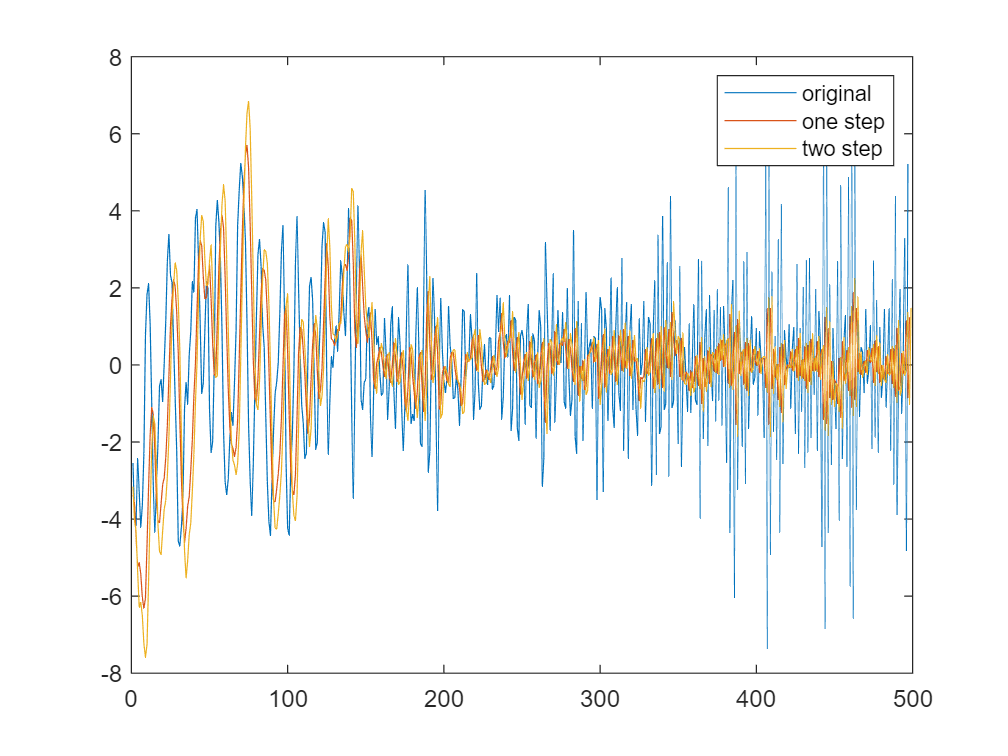

figure;
plot(y(4:end))
hold on
plot(yhat1(4:end))
hold on
plot(yhat2(4:end))
legend("original", "one step", "two step")
hold off